# Global Sensitivity Analysis for Multiple Interpretive Models With Uncertain Parameters——Constrained scenario

# 
$$A M A \mathrm{SM}_{\theta_{i}^{j}}=\frac{w\left(M^{j}\right)}{\mathfrak{\Im}}\left\{\begin{array}{c}
\left|{SM}[\Delta]-{SM}_{\theta^{j}}\left[\Delta \mid M^{j}\right]\right|+E_{\theta_{i}^{j}}\left[\left|{SM}_{\theta^{j}}\left[\Delta \mid M^{j}\right]-{SM}_{-\theta_{i}^{j}}\left[\Delta \mid M^{j}\right]\right|\right] \\
\end{array}\right\}$$


#### 
$$\mathfrak{F}=\left\{\begin{array}{ccc}
|{SM}[\Delta]| & \text { if } &{SM}[\Delta] \neq 0 \\
1 & \text { if } & {SM}[\Delta]=0
\end{array}\right.$$


# Unconstrained scenario & Constrained scenario

## 0 参数

   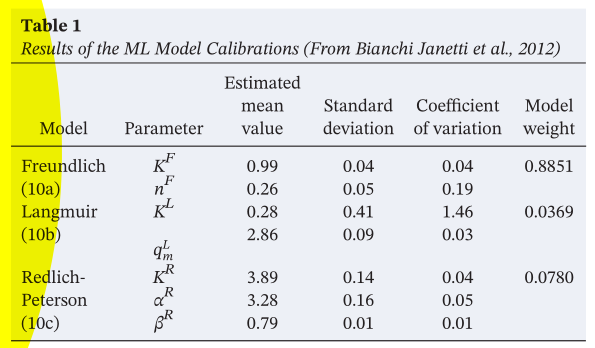

clear;clc;
N=1000;
nn=25:25:N;
% 非约束情景
%
w=[1/3;1/3;1/3];

cv0=1+0.7*randn(4*N,1);cv0=cv0(cv0<=(1+0.7*3^0.5));cv0=cv0(cv0>=(1-0.7*3^0.5));cv0=cv0(cv0>=0);%%协方差系数规定为0.7，给定每个参数均匀分布的区间

KF=0.99*cv0(randperm(size(cv0,1),N));
nF=0.26*cv0(randperm(size(cv0,1),N));
KL=0.28*cv0(randperm(size(cv0,1),N));
qL=2.86*cv0(randperm(size(cv0,1),N));
KR=3.89*cv0(randperm(size(cv0,1),N));
aR=3.28*cv0(randperm(size(cv0,1),N));
bR=0.79*cv0(randperm(size(cv0,1),N));

% % % 约束情景
% w=[0.8851;0.0369;0.0780];
% 
% X0 = sobolr(N,8);
% KF=0.99+0.04*soboln(X0(:,1));
% nF=0.26+0.05*soboln(X0(:,2));
% qL=2.86+0.09*soboln(X0(:,3));
% KR=3.89+0.14*soboln(X0(:,4));
% aR=3.28+0.16*soboln(X0(:,5));
% bR=0.79+0.01*soboln(X0(:,6));
% KL(1:N,1)=0.28+0.41*soboln(X0(:,7));
% KL(N+1:2*N,1)=0.28+0.41*soboln(X0(:,8));
% KL=KL(KL>0);id=randperm(size(KL,1),N);KL=KL(id);

% KF=0.99+0.04*randn(N,1);
% nF=0.26+0.05*randn(N,1);
% KL=0.28+0.41*randn(2*N,1);KL=KL(KL>0);id=randperm(size(KL,1),N);KL=KL(id);
% qL=2.86+0.09*randn(N,1);
% KR=3.89+0.14*randn(N,1);
% aR=3.28+0.16*randn(N,1);
% bR=0.79+0.01*randn(N,1);


## 1 SM

### 1.1 计算

f = figure;
f.Position(3) = 2*f.Position(3);%%???
% subplot(2,2,1);subplot(2,2,2);subplot(2,2,3);subplot(2,2,4);
x0_F = [5 5 5 20.6 36.8 54.8 74 94.3 115];%%%随着初始浓度的不同而变化
x0_L = [5 5 5 16 35 57.6 81 106 130];
x0_R = [5 5 5 20.6 37.6 56.6 76.9 98 120];
c0 =   [20 30 50 75 100 125 150 175 200];
cc=size(c0,2);

SM=zeros(4,cc,4);wbm=zeros(3,cc,4);% SM：4页cc列4行，四个SM，13个c0，1~4行分别对应F、L、R及整个模型
AMASM=zeros(7,cc,4);%7个参数，cc浓度 4是SM 
btm=zeros(3,cc,4);% 3个模型  model-choice
pa=zeros(7,cc,4); % parameter-choice
AVD=zeros(7,cc);%%%%AMAV的单模型结果
STi=zeros(7,cc,2);%基于方差的指数
SDi=zeros(7,cc,2);%基于方差的指数--单模型
AMAVK=zeros(1,cc); STK=zeros(1,cc); SiK=zeros(1,cc);
SM_er=zeros(length(nn),9,cc); PA_er=zeros(length(nn),9,cc);
minF=zeros(cc,1); minL=zeros(cc,1); minR=zeros(cc,1);
start = tic;
for i=1:cc
     disp(i);
    yF=MF(c0(i),N,KF,nF,x0_F(i));
    yL=ML(c0(i),N,KL,qL,x0_L(i));
    yR=MR(c0(i),N,KR,aR,bR,x0_R(i));
    minF(i)=min(yF(:));
    minL(i)=min(yL(:));
    minR(i)=min(yR(:));

    %%%%循环保存文件
    filename = strcat('yF',num2str(i),'.mat');
    save(filename,'yF' );
    filename = strcat('yL',num2str(i),'.mat');
    save(filename,'yL');
    filename = strcat('yR',num2str(i),'.mat');
    save(filename,'yR');

    [SM_er(:,:,i),PA_er(:,:,i)]=shou(nn,yF,yL,yR);

    SM(:,i,1)=SM1(yF,yL,yR,w);
    [SM(:,i,2),wbm(1:2,i,2)]=SM2(yF,yL,yR,w);
    [SM(:,i,3),wbm(:,i,3)]=SM3(yF,yL,yR,w,SM(:,i,1),SM(:,i,2));
    [SM(:,i,4),wbm(:,i,4)]=SM4(yF,yL,yR,w,SM(:,i,1),SM(:,i,2),SM(:,i,3));%%

    [AMASM(:,i,1),btm(:,i,1),pa(:,i,1)]=AMASM1(yF,yL,yR,SM,w,i);
    [AMASM(:,i,2),btm(:,i,2),pa(:,i,2),AVD(:,i)]=AMASM2(yF,yL,yR,SM,w,i);
    [AMASM(:,i,3),btm(:,i,3),pa(:,i,3)]=AMASM3(yF,yL,yR,SM,w,i);
    [AMASM(:,i,4),btm(:,i,4),pa(:,i,4)]=AMASM4(yF,yL,yR,SM,w,i);

    %基于方差的指数
    
    [STi(:,i,:),SDi(:,i,:),]=Svar(yF,yL,yR,w,wbm,SM,i,N);

%K出现在3个模型中FLR-AMAV  -ST  -Si
%AMAV
AMAVK(i)=AMASM(1,i,2)+AMASM(3,i,2)+AMASM(5,i,2);
%STK
STK(i)=STi(1,i,1)+STi(3,i,1)+STi(5,i,1);
SiK(i) =STi(1,i,2)+STi(3,i,2)+STi(5,i,2);

%     Update the plot
    D = duration(0,0,toc(start),'Format','hh:mm:ss');
    title( ...
        "循环: " + i + "/ " + cc+...
        " 用时: " + string(D))
    drawnow
end

     1

     2

     3

     4

     5

     6

     7

     8

     9



### 1.2 绘图

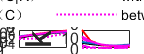

c01=log10(c0');
SMLOG(:,:,1)=log10(SM(:,:,1)');
SMLOG(:,:,2)=log10(SM(:,:,2)');wbV=log10(wbm(1:2,:,2)');
clf;
createfigure_SM(f,c01, SMLOG(:,:,1), SM(:,:,3)',wbm(:,:,3)', SMLOG(:,:,2),wbV, SM(:,:,4)',wbm(:,:,4)')

1.3 收敛检查

function [SM_er,PA_er]=shou(nn,yF,yL,yR)
zl=length(nn);
VFf=zeros(zl); VLl=zeros(zl); VRr=zeros(zl); rFf=zeros(zl); rLl=zeros(zl); rRr=zeros(zl); kFf=zeros(zl); kLl=zeros(zl); kRr=zeros(zl);
V_KF=zeros(zl);V_KL=zeros(zl);V_KR=zeros(zl);r_KF=zeros(zl);r_KL=zeros(zl);r_KR=zeros(zl);k_KF=zeros(zl);k_KL=zeros(zl);k_KR=zeros(zl);
SM_er=zeros(zl,9);PA_er=zeros(zl,9);

for i=1:zl
    VFf(i) =var(reshape(yF(1:nn(i),1:nn(i)),[1 nn(i)*nn(i)] ));
    VLl(i) =var(reshape(yL(1:nn(i),1:nn(i)),[1 nn(i)*nn(i)] ));
    VRr(i) =var(reshape(yR(1:nn(i),1:nn(i),1:nn(i)),[1 nn(i)*nn(i)*nn(i)] ));
    rFf(i) =skewness(reshape(yF(1:nn(i),1:nn(i)),[1 nn(i)*nn(i)] ));
    rLl(i) =skewness(reshape(yL(1:nn(i),1:nn(i)),[1 nn(i)*nn(i)] ));
    rRr(i) =skewness(reshape(yR(1:nn(i),1:nn(i),1:nn(i)),[1 nn(i)*nn(i)*nn(i)] ));
    kFf(i) =kurtosis(reshape(yF(1:nn(i),1:nn(i)),[1 nn(i)*nn(i)] ));
    kLl(i) =kurtosis(reshape(yL(1:nn(i),1:nn(i)),[1 nn(i)*nn(i)] ));
    kRr(i) =kurtosis(reshape(yR(1:nn(i),1:nn(i),1:nn(i)),[1 nn(i)*nn(i)*nn(i)] ));
    V_KF(i)=mean(abs( VFf(i)- var(yF(1:nn(i),1:nn(i)),0,2 )));
    V_KL(i)=mean(abs( VLl(i)- var(yL(1:nn(i),1:nn(i)),0,2 )));
    V_KR(i)=mean(abs( VRr(i)- var(yR(1:nn(i),1:nn(i),1:nn(i)),0,[2 3] )));
    r_KF(i)=mean(abs( rFf(i)- skewness(yF(1:nn(i),1:nn(i)),0,2 )));
    r_KL(i)=mean(abs( rLl(i)- skewness(yL(1:nn(i),1:nn(i)),0,2 )));
    r_KR(i)=mean(abs( rRr(i)- skewness(yR(1:nn(i),1:nn(i),1:nn(i)),0,[2 3] )));
    k_KF(i)=mean(abs( kFf(i)- kurtosis(yF(1:nn(i),1:nn(i)),0,2 )));
    k_KL(i)=mean(abs( kLl(i)- kurtosis(yL(1:nn(i),1:nn(i)),0,2 )));
    k_KR(i)=mean(abs( kRr(i)- kurtosis(yR(1:nn(i),1:nn(i),1:nn(i)),0,[2 3] )));
end

for i2=1:zl
SM_er(i2,1) = abs(VFf(zl)-VFf(i2))/VFf(zl);                                                                                                                                                                                                                                                                                
SM_er(i2,2) = abs(VLl(zl)-VLl(i2))/VLl(zl);
SM_er(i2,3) = abs(VRr(zl)-VRr(i2))/VRr(zl);
SM_er(i2,4) = abs(rFf(zl)-rFf(i2))/rFf(zl);
SM_er(i2,5) = abs(rLl(zl)-rLl(i2))/rLl(zl);
SM_er(i2,6) = abs(rRr(zl)-rRr(i2))/rRr(zl);
SM_er(i2,7) = abs(kFf(zl)-kFf(i2))/kFf(zl);
SM_er(i2,8) = abs(kLl(zl)-kLl(i2))/kLl(zl);
SM_er(i2,9) = abs(kRr(zl)-kRr(i2))/kRr(zl);
PA_er(i2,1)=abs(V_KF(zl)-V_KF(i2))/V_KF(zl);
PA_er(i2,2)=abs(r_KF(zl)-r_KF(i2))/r_KF(zl);
PA_er(i2,3)=abs(k_KF(zl)-k_KF(i2))/k_KF(zl);
PA_er(i2,4)=abs(V_KL(zl)-V_KL(i2))/V_KL(zl);
PA_er(i2,5)=abs(r_KL(zl)-r_KL(i2))/r_KL(zl);
PA_er(i2,6)=abs(k_KL(zl)-k_KL(i2))/k_KL(zl);
PA_er(i2,7)=abs(V_KR(zl)-V_KR(i2))/V_KR(zl);
PA_er(i2,8)=abs(r_KR(zl)-r_KR(i2))/r_KR(zl);
PA_er(i2,9)=abs(k_KR(zl)-k_KR(i2))/k_KR(zl);
end
end

## 模型公式

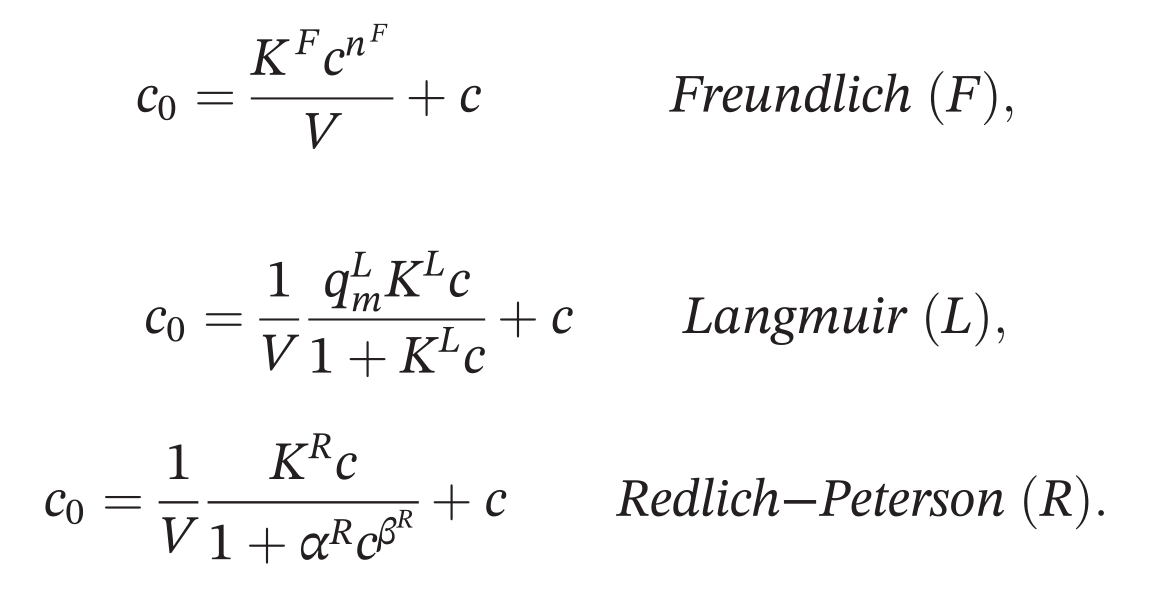

### Freundlich (F)

function [y]=MF(c0,N,KF,nF,~)
    syms x
    y=zeros(N,N);
    for i=1:N
        for j=1:N
            f=@(x)(c0-x)*0.04-KF(i)*x^nF(j);
%            fun = @(c)(c0-c)*0.04-KF(i)*c^nF(j);
%            [y(i,j),~,~] = xianjie(f,x0_F,1e-3);                            
               [ y(i,j),~,~,~,~]=Bisection(f,0,200,0.00001);
        end
    end
%     y=reshape(y,[N^2,1]);
%     y(y<0)=0;
end

### Langmuir (L)

function [y]=ML(c0,N,KL,qL,~)
    syms c
    y=zeros(N,N);
    for i=1:N
        for j=1:N
            f=@(x)(c0-x)*0.04*(1+KL(i)*x)-x*qL(j)*KL(i);
%            [y(i,j),~,~] = xianjie(f,x0_L,1e-3);
           [ y(i,j),~,~,~,~]=Bisection(f,0,200,0.00001);
        end
    end
%     y=reshape(y,[N^2,1]);
%     y(y<0)=0;
end

### Redlich-Peterson (R)

function [y]=MR(c0,N,KR,aR,bR,~)
    syms c
    y=zeros(N,N,N);
    for i=1:N
        for j=1:N
            for k=1:N
                f=@(c)(c0-c)*0.04*(1+aR(j)*c^bR(k))-KR(i)*c;
%               [y(i,j,k),~,~] = xianjie(f,x0_R,1e-3);
               [ y(i,j,k),~,~,~,~]=Bisection(f,0,200,0.00001);
            end
        end
    end
%     y=reshape(y,[N^3,1]);
%     y(y<0)=0;
end

## $SM^{(n)}[{\Delta}]$公式

### 
$$E[\Delta]=\sum_{j=1}^{N_{M}} w\left(M^{j}\right) E_{\theta^{j}}\left[\Delta \mid M^{j}\right]$$


function [E]=SM1(yF,yL,yR,w)
    yF=yF(yF>0);yL=yL(yL>0);yR=yR(yR>0);
    E=zeros(4,1);  
    E(1)=mean(yF,'all');
    E(2)=mean(yL,'all');
    E(3)=mean(yR,'all');
    E(4)=w(1)*E(1)+w(2)*E(2)+w(3)*E(3);
end

### 
$$\begin{array}{l}
V[\Delta]=\sum_{j=1}^{N_{M}} w\left(M^{j}\right) V_{\theta^{j}}\left[\Delta \mid M^{j}\right]+\sum_{j=1}^{N_{M}} w\left(M^{j}\right)\left(E[\Delta]-E_{\theta^{j}}\left[\Delta \mid M^{j}\right]\right)^{2}\\
\end{array}
\end{array}$$


function [V,wb]=SM2(yF,yL,yR,w)
    yF=yF(yF>0);yL=yL(yL>0);yR=yR(yR>0);
    V=zeros(4,1); 
    wb=zeros(2,1);
    [E]=SM1(yF,yL,yR,w);
    E=w.*((E(4)-E(1:3)).^2);
    wb(2)=sum(E);%%%%%%%%%%%%%%%%between-model
    
    V(1)=var(yF,0,'all');
    V(2)=var(yL,0,'all');
    V(3)=var(yR,0,'all');
    wb(1)=sum(w.*V(1:3),"all");%%%witnin-model
    V(4)=wb(1)+wb(2);
end

### 
$$\gamma[\Delta]=\sum_{j=1}^{N_{M}}\left(\frac{V_{\theta}\left[\Delta \mid M^{j}\right]}{V[\Delta]}\right)^{3 / 2} w\left(M^{j}\right) \gamma_{\theta^{j}}\left[\Delta \mid M^{j}\right]-\sum_{j=1}^{N_{M}} w\left(M^{j}\right) \frac{\left(E[\Delta]-E_{\theta^{j}}\left[\Delta \mid M^{j}\right]\right)^{3}}{(V[\Delta])^{3 / 2}}
-3 \sum_{j=1}^{N_{M}} \frac{V_{\theta^{j}}\left[\Delta \mid M^{j}\right]}{(V[\Delta])^{3 / 2}} w\left(M^{j}\right)\left(E[\Delta]-E_{\theta^{j}}\left[\Delta \mid M^{j}\right]\right)\\
$$


% skewness()
function [sk,wbm]=SM3(yF,yL,yR,w,E,V)
    yF=yF(yF>0);yL=yL(yL>0);yR=yR(yR>0);
    sk=zeros(4,1); 
    wbm=zeros(3,1);
    sk(1)=skewness(yF,0,'all');
    sk(2)=skewness(yL,0,'all');
    sk(3)=skewness(yR,0,'all');
    
    w0=(V(1:3)./V(4)).^(3/2).*w.*sk(1:3);
    wbm(1)=sum(w0);
    b0=w.*((E(4)-E(1:3)).^3)./(V(4)^1.5);
    wbm(2)=sum(b0);
    m0=3.*V(1:3)./(V(4)^1.5).*w.*(E(4)-E(1:3));
    wbm(3)=sum(m0);
    
    sk(4)=wbm(1)-wbm(2)-wbm(3);
end

### 
$$k[\Delta]=\sum_{j=1}^{N_{M}}\left(\frac{V_{\theta^{j}}\left[\Delta \mid M^{j}\right]}{V[\Delta]}\right)^{2} w\left(M^{j}\right) k_{\theta}\left[\Delta \mid M^{j}\right]+\sum_{j=1}^{N_{M}} w\left(M^{j}\right) \frac{\left(E[\Delta]-E_{\theta}\left[\Delta \mid M^{j}\right]\right)^{4}}{(V[\Delta])^{2}}
\begin{array}{c}
+4 \sum_{j=1}^{N_{M}} w\left(M^{j}\right)\left(\frac{E[\Delta]-E_{\theta^{j}}\left[\Delta \mid M^{j}\right]}{V[\Delta]}\right)^{2}\left\{\frac{3}{2} V_{\theta}\left[\Delta \mid M^{j}\right]\right. & \left.-\frac{\gamma_{\theta^{j}}\left[\Delta \mid M^{j}\right]\left(V_{\theta}\left[\Delta \mid M^{j}\right]\right)^{3 / 2}}{E[\Delta]-E_{\theta^{j}}\left[\Delta \mid M^{j}\right]}\right\} 
\end{array}$$


% kurtosis()
function [ku,wbm]=SM4(yF,yL,yR,w,E,V,sk)
    yF=yF(yF>0);yL=yL(yL>0);yR=yR(yR>0);
    ku=zeros(4,1); 
    wbm=zeros(3,1);
    ku(1)=kurtosis(yF,0,'all');
    ku(2)=kurtosis(yL,0,'all');
    ku(3)=kurtosis(yR,0,'all');
    
    w0=(V(1:3)./V(4)).^2.*w.*ku(1:3);
    wbm(1)=sum(w0);
    b0=w.*((E(4)-E(1:3)).^4)./(V(4).^2);
    wbm(2)=sum(b0);
    m0=4.*w.*((E(4)-E(1:3))./V(4)).^2.*(3/2.*V(1:3)-sk(1:3).*(V(1:3).^1.5)./(E(4)-E(1:3)));
    wbm(3)=sum(m0);
    
    ku(4)=wbm(1)+wbm(2)+wbm(3);
end


## $A M A \mathrm{SM}_{\theta_{i}^{j}}$公式


$$A M A \mathrm{SM}_{\theta_{i}^{j}}=\frac{w\left(M^{j}\right)}{\mathfrak{\Im}}\left\{\begin{array}{c}
\left|{SM}[\Delta]-{SM}_{\theta^{j}}\left[\Delta \mid M^{j}\right]\right|+E_{\theta_{i}^{j}}\left[\left|{SM}_{\theta^{j}}\left[\Delta \mid M^{j}\right]-{SM}_{-\theta_{i}^{j}}\left[\Delta \mid M^{j}\right]\right|\right] \\
\end{array}\right\}$$



$$A M A \mathrm{SM}_{\theta_{i}} \equiv A M A \mathrm{SM}_{\theta_{i}}=\frac{1}{\mathfrak{\Im}} E_{\theta_{i}^{j}}\left[\left|{SM}_{\theta^{j}}\left[\Delta \mid M^{j}\right]-\mathrm{SM}_{-\theta_{i}^{j}}\left[\Delta \mid M^{j}\right]\right|\right]$$



$$\mathfrak{F}=\left\{\begin{array}{ccc}
|{SM}[\Delta]| & \text { if } &{SM}[\Delta] \neq 0 \\
1 & \text { if } & {SM}[\Delta]=0
\end{array}\right.$$


AMAE

function [AMAE,btm_E,pa_E]=AMASM1(yF,yL,yR,SM,w,i)
    if SM(4,i,1)==0
        F=1;
    else
        F=abs(SM(4,i,1));
    end
    btm_E=zeros(3,1);
    AMAE=zeros(7,1);
%%%计算model-choice项
   btm_E(1)=abs(SM(4,i,1)-SM(1,i,1))*w(1)/F;
   btm_E(2)=abs(SM(4,i,1)-SM(2,i,1))*w(2)/F;
   btm_E(3)=abs(SM(4,i,1)-SM(3,i,1))*w(3)/F;

%%%计算parameter-choice项
   pa_E=zeros(7,1);  %%行代表参数，列代表模型，3列 FRL三个模型
   pa_E(1)=mean(abs(SM(1,i,1)- mean(yF,2)))*w(1)/F;
   pa_E(2)=mean(abs(SM(1,i,1)- mean(yF,1)))*w(1)/F;
   pa_E(3)=mean(abs(SM(2,i,1)- mean(yL,2)))*w(2)/F;
   pa_E(4)=mean(abs(SM(2,i,1)- mean(yL,1)))*w(2)/F;
   pa_E(5)=mean(abs(SM(3,i,1)- mean(yR,[2 3])))*w(3)/F;
   pa_E(6)=mean(abs(SM(3,i,1)- mean(yR,[1 3])))*w(3)/F;
   pa_E(7)=mean(abs(SM(3,i,1)- mean(yR,[1 2])))*w(3)/F;

   AMAE(1)=btm_E(1)+pa_E(1);  %KF
   AMAE(2)=btm_E(1)+pa_E(2);
   AMAE(3)=btm_E(2)+pa_E(3);
   AMAE(4)=btm_E(2)+pa_E(4);
   AMAE(5)=btm_E(3)+pa_E(5);
   AMAE(6)=btm_E(3)+pa_E(6);
   AMAE(7)=btm_E(3)+pa_E(7);
end
%    l=length(size(yF));
%     AMAE=zeros(2*l+1,1);
%    AMAEj=zeros(l,1);
%    AMAE(2*l+1)=sm;
    
%    AMAEj(1)=mean(abs(mean(mean(yF,2),3)),'all')/F;
%    AMAE(l+1)=AMAEj(1)*w;
%   AMAE(1)=w*abs(sm-smj)/F+AMAE(l+1);
    
%    AMAEj(2)=mean(abs(mean(mean(yF,1),3)),'all')/F;
%    AMAE(l+2)=AMAEj(2)*w;
%    AMAE(2)=w*abs(sm-smj)/F+AMAE(l+2);
%    if l==3
%        AMAEj(3)=mean(abs(mean(mean(yF,1),2)),'all')/F;
%        AMAE(l+3)=AMAEj(3)*w;
%        AMAE(3)=w*abs(sm-smj)/F+AMAE(l+3);
%   end
%end

AMAV

function [AMAV,btm_V,pa_V,AVD]=AMASM2(yF,yL,yR,SM,w,i)
    if SM(4,i,2)==0
        F=1;
    else
        F=abs(SM(4,i,2));
    end
    btm_V=zeros(3,1);
    AMAV=zeros(7,1); AVD=zeros(7,1);
%%%计算model-choice项
   btm_V(1)=abs(SM(4,i,2)-SM(1,i,2))*w(1)/F;
   btm_V(2)=abs(SM(4,i,2)-SM(2,i,2))*w(2)/F;
   btm_V(3)=abs(SM(4,i,2)-SM(3,i,2))*w(3)/F;

%%%计算parameter-choice项
   pa_V=zeros(7,1);  %%行代表参数，列代表模型，3列 FRL三个模型
   pa_V(1)=mean(abs(SM(1,i,2)- var(yF,0,2)))*w(1)/F;
   pa_V(2)=mean(abs(SM(1,i,2)- var(yF,0,1)))*w(1)/F;
   pa_V(3)=mean(abs(SM(2,i,2)- var(yL,0,2)))*w(2)/F;
   pa_V(4)=mean(abs(SM(2,i,2)- var(yL,0,1)))*w(2)/F;
   pa_V(5)=mean(abs(SM(3,i,2)- var(yR,0,[2 3])))*w(3)/F;
   pa_V(6)=mean(abs(SM(3,i,2)- var(yR,0,[1 3])))*w(3)/F;
   pa_V(7)=mean(abs(SM(3,i,2)- var(yR,0,[1 2])))*w(3)/F;
  

   AMAV(1)=btm_V(1)+ pa_V(1);  %KF
   AMAV(2)=btm_V(1)+ pa_V(2);
   AMAV(3)=btm_V(2)+ pa_V(3);
   AMAV(4)=btm_V(2)+ pa_V(4);
   AMAV(5)=btm_V(3)+ pa_V(5);
   AMAV(6)=btm_V(3)+ pa_V(6);
   AMAV(7)=btm_V(3)+ pa_V(7);

   AVD(1)=mean(abs(SM(1,i,2)- var(yF,0,2)))/SM(1,i,2);
   AVD(2)=mean(abs(SM(1,i,2)- var(yF,0,1)))/SM(1,i,2);
   AVD(3)=mean(abs(SM(2,i,2)- var(yL,0,2)))/SM(2,i,2);
   AVD(4)=mean(abs(SM(2,i,2)- var(yL,0,1)))/SM(2,i,2);
   AVD(5)=mean(abs(SM(3,i,2)- var(yR,0,[2 3])))/SM(3,i,2);
   AVD(6)=mean(abs(SM(3,i,2)- var(yR,0,[1 3])))/SM(3,i,2);
   AVD(7)=mean(abs(SM(3,i,2)- var(yR,0,[1 2])))/SM(3,i,2);
  
end

AMAr

function [AMAr,btm_r,pa_r]=AMASM3(yF,yL,yR,SM,w,i)
    if SM(4,i,3)==0
        F=1;
    else
        F=abs(SM(4,i,3));
    end
    btm_r=zeros(3,1);
    AMAr=zeros(7,1);
%%%计算model-choice项
   btm_r(1)=abs(SM(4,i,3)-SM(1,i,3))*w(1)/F;
   btm_r(2)=abs(SM(4,i,3)-SM(2,i,3))*w(2)/F;
   btm_r(3)=abs(SM(4,i,3)-SM(3,i,3))*w(3)/F;

%%%计算parameter-choice项
   pa_r=zeros(7,1);  %%行代表参数，列代表模型，3列 FRL三个模型
   pa_r(1)=mean(abs(SM(1,i,3)- skewness(yF,1,2)))*w(1)/F;
   pa_r(2)=mean(abs(SM(1,i,3)- skewness(yF,1,1)))*w(1)/F;
   pa_r(3)=mean(abs(SM(2,i,3)- skewness(yL,1,2)))*w(2)/F;
   pa_r(4)=mean(abs(SM(2,i,3)- skewness(yL,1,1)))*w(2)/F;
   pa_r(5)=mean(abs(SM(3,i,3)- skewness(yR,1,[2 3])))*w(3)/F;
   pa_r(6)=mean(abs(SM(3,i,3)- skewness(yR,1,[1 3])))*w(3)/F;
   pa_r(7)=mean(abs(SM(3,i,3)- skewness(yR,1,[1 2])))*w(3)/F;
   
   AMAr(1)=btm_r(1)+pa_r(1);  %KF
   AMAr(2)=btm_r(1)+pa_r(2);
   AMAr(3)=btm_r(2)+pa_r(3);
   AMAr(4)=btm_r(2)+pa_r(4);
   AMAr(5)=btm_r(3)+pa_r(5);
   AMAr(6)=btm_r(3)+pa_r(6);
   AMAr(7)=btm_r(3)+pa_r(7);
end

AMAk

function [AMAk,btm_k,pa_k]=AMASM4(yF,yL,yR,SM,w,i)
    if SM(4,i,4)==0
        F=1;
    else
        F=abs(SM(4,i,4));
    end
    btm_k=zeros(3,1);
    AMAk=zeros(7,1);
%%%计算model-choice项
   btm_k(1)=abs(SM(4,i,4)-SM(1,i,4))*w(1)/F;
   btm_k(2)=abs(SM(4,i,4)-SM(2,i,4))*w(2)/F;
   btm_k(3)=abs(SM(4,i,4)-SM(3,i,4))*w(3)/F;

%%%计算parameter-choice项
   pa_k=zeros(7,1);  %%行代表参数，列代表模型，3列 FRL三个模型
   pa_k(1)=mean(abs(SM(1,i,4)- kurtosis(yF,1,2)))*w(1)/F;
   pa_k(2)=mean(abs(SM(1,i,4)- kurtosis(yF,1,1)))*w(1)/F;
   pa_k(3)=mean(abs(SM(2,i,4)- kurtosis(yL,1,2)))*w(2)/F;
   pa_k(4)=mean(abs(SM(2,i,4)- kurtosis(yL,1,1)))*w(2)/F;
   pa_k(5)=mean(abs(SM(3,i,4)- kurtosis(yR,1,[2 3])))*w(3)/F;
   pa_k(6)=mean(abs(SM(3,i,4)- kurtosis(yR,1,[1 3])))*w(3)/F;
   pa_k(7)=mean(abs(SM(3,i,4)- kurtosis(yR,1,[1 2])))*w(3)/F;
   
   AMAk(1)=btm_k(1)+pa_k(1);  %KF
   AMAk(2)=btm_k(1)+pa_k(2);
   AMAk(3)=btm_k(2)+pa_k(3);
   AMAk(4)=btm_k(2)+pa_k(4);
   AMAk(5)=btm_k(3)+pa_k(5);
   AMAk(6)=btm_k(3)+pa_k(6);
   AMAk(7)=btm_k(3)+pa_k(7);
end

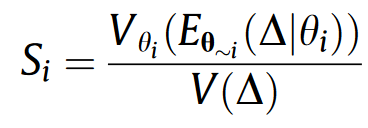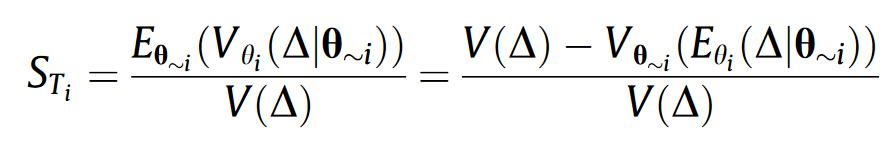

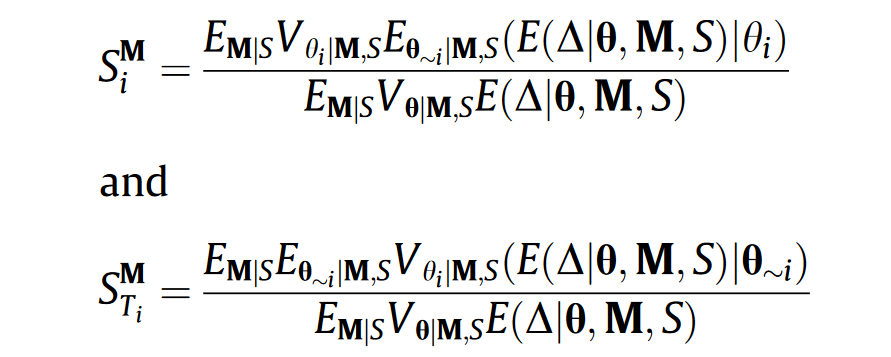

%%%计算方差的敏感性指数一阶和总的   单模型中结果
function [STi,SDi]=Svar(yF,yL,yR,w,wbm,SM,i,N)
STi=zeros(7,1,2);SDi=zeros(7,1,2);

STi(1,1,1)= (SM(1,i,2) - var(mean(yF,1)))*w(1)/wbm(1,i,2);
STi(2,1,1)= (SM(1,i,2) - var(mean(yF,2)))*w(1)/wbm(1,i,2);
STi(3,1,1)= (SM(2,i,2) - var(mean(yL,1)))*w(2)/wbm(1,i,2);
STi(4,1,1)= (SM(2,i,2) - var(mean(yL,2)))*w(2)/wbm(1,i,2);
STi(5,1,1)= (SM(3,i,2) -var(reshape(mean(yR,1),[1,N*N])))*w(3)/wbm(1,i,2);
STi(6,1,1)= (SM(3,i,2) -var(reshape(mean(yR,2),[1,N*N])))*w(3)/wbm(1,i,2);
STi(7,1,1)= (SM(3,i,2) -var(reshape(mean(yR,3),[1,N*N])))*w(3)/wbm(1,i,2);

STi(1,1,2)= var(mean(yF,2))*w(1)/wbm(1,i,2);
STi(2,1,2)= var(mean(yF,1))*w(1)/wbm(1,i,2);
STi(3,1,2)= var(mean(yL,2))*w(2)/wbm(1,i,2);
STi(4,1,2)= var(mean(yL,1))*w(2)/wbm(1,i,2);
STi(5,1,2)= var(mean(yR,[2 3]))*w(3)/wbm(1,i,2);
STi(6,1,2)= var(mean(yR,[1 3]))*w(3)/wbm(1,i,2);
STi(7,1,2)= var(mean(yR,[1 2]))*w(3)/wbm(1,i,2);

SDi(1,1,1)= (SM(1,i,2) - var(mean(yF,1)))/SM(1,i,2);
SDi(2,1,1)= (SM(1,i,2) - var(mean(yF,2)))/SM(1,i,2);
SDi(3,1,1)= (SM(2,i,2) - var(mean(yL,1)))/SM(2,i,2);
SDi(4,1,1)= (SM(2,i,2) - var(mean(yL,2)))/SM(2,i,2);
SDi(5,1,1)= (SM(3,i,2) -var(reshape(mean(yR,1),[1,N*N])))/SM(3,i,2);
SDi(6,1,1)= (SM(3,i,2) -var(reshape(mean(yR,2),[1,N*N])))/SM(3,i,2);
SDi(7,1,1)= (SM(3,i,2) -var(reshape(mean(yR,3),[1,N*N])))/SM(3,i,2);

SDi(1,1,2)= var(mean(yF,2))/SM(2,i,2);
SDi(2,1,2)= var(mean(yF,1))/SM(2,i,2);
SDi(3,1,2)= var(mean(yL,2))/SM(2,i,2);
SDi(4,1,2)= var(mean(yL,1))/SM(2,i,2);
SDi(5,1,2)= var(mean(yR,[2 3]))/SM(3,i,2);
SDi(6,1,2)= var(mean(yR,[1 3]))/SM(3,i,2);
SDi(7,1,2)= var(mean(yR,[1 2]))/SM(3,i,2);

end